# TP 3 - 

## Décomposition en élément simple (Ex 47 p 28)

### Initialisation des valeurs

s = tf("s");
Y = 1 / ((s + 1)*(s + 2));

### Première méthode 

[r, p, k] = residue(Y.num{1}, Y.den{1})

r =     -1
     1


p =     -2
    -1



k =

     []



On obtient :

- r : Les valeurs du numérateur de la décomposition en élément simple.

- p : Les valeurs du dénominateurs de la décomposition en élément simple.

On construit les éléments de la decomposition en élément simple.

Y1 = r(1)/(s - p(1));
Y2 = r(2)/(s - p(2));

On envoie une impulsion sur chaque système et on les ajoute. Cela nous donne l'évolution au cours du temps.

[Yres1, t1] = impulse(Y1,10)

Yres1 =    -1.0000
   -0.9120
   -0.8317
   -0.7584
   -0.6917
   -0.6308
   -0.5752
   -0.5246
   -0.4784
   -0.4363


t1 =          0
    0.0461
    0.0922
    0.1382
    0.1843
    0.2304
    0.2765
    0.3226
    0.3687
    0.4147


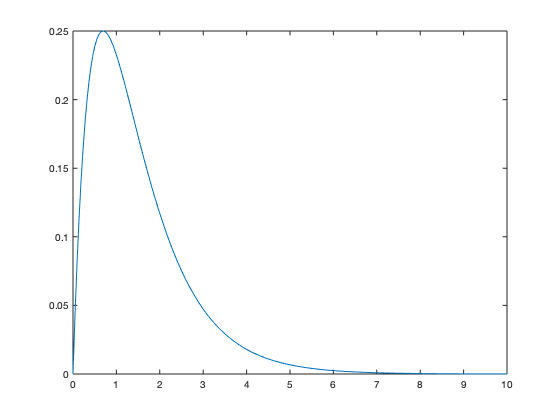

Yres2 = impulse(Y2,t1);
Yres = Yres1 + Yres2;
plot(t1, Yres)

## Exercice 53 p 30

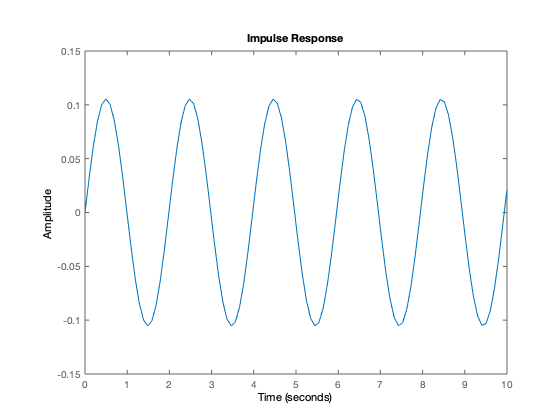

m = 3;
k = 30;
X = 1 / (m * s ^ 2 + k);
impulse(X, 10)                            